## Testing ArmPos class

### Testing ArmPos.draw

plotting random positions for each point

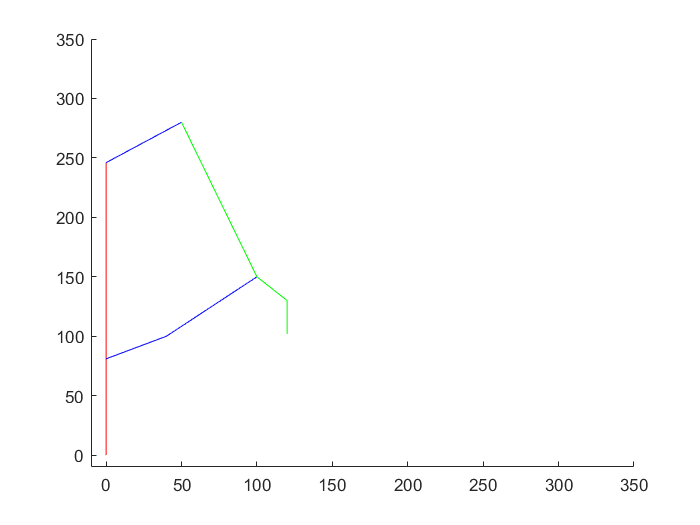

addpath("Kinematics")
pos = ArmPos();%initiate armposition object
pos.A = [50,280]; %setting position of the arm with random numbers
pos.B = [100,150];
pos.C = [120,130];
pos = pos.setD; %also testing setD
pos.E = [40,100];
pos.draw(); %drawing the a current configuration of the arm

### Testing ACtoB

what should be seen is that the arm from A to C is now straight

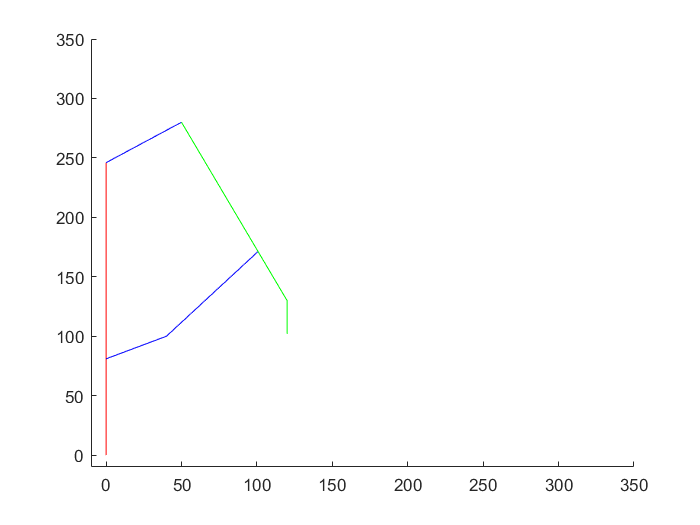

pos = pos.ACtoB();
pos.draw();

## Testing getAngle

pos.getAngle([0,0],[1,1]); % 45 degrees
pos.getAngle([0,0],[1,-1]); %-45 degrees
pos.getAngle([0,0],[-1,-1]); %-135 degrees
pos.getAngle([0,0],[-1,1]); %135 degrees

phi = 200;
phi_rad = 2*pi*phi/360

phi_rad = 3.4907

x = cos(phi_rad);
y = sin(phi_rad);
pos.getAngle([0,0],[x,y])

ans = -2.7925

pos.getAngle(pos.Z,pos.A) 

ans = 0.5972

pos = pos.getAngles

pos =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 28
          X: [0 81]
          Z: [0 246]
    phiXmin: 0.2000
    phiXmax: 1.4708
    phiZmin: -0.4000
    phiZmax: 0.3000
    phi1min: -2.3562
    phi1max: 2.3562
      theta: 0
          A: [50 280]
          B: [100.7463 171.2580]
          C: [120 130]
          D: [120 102]
          E: [40 100]
       phiX: 0.4434
       phiZ: 0.5972
       phi1: 0.4214


## Testing validation

pos.validate(true)

PhiZ is invalid
Phi Z is incorrect
|EX| != L3
|BE| != L4
|AZ| != L5
|BC| != L7


ans = logical
   0


ans =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 28
          X: [0 81]
          Z: [0 246]
    phiXmin: 0.2000
    phiXmax: 1.4708
    phiZmin: -0.4000
    phiZmax: 0.3000
    phi1min: -2.3562
    phi1max: 2.3562
      theta: 0
          A: [50 280]
          B: [100.7463 171.2580]
          C: [120 130]
          D: [120 102]
          E: [40 100]
       phiX: 0.4434
       phiZ: 0.5972
       phi1: 0.4214


pos.draw()

## Testing generating position from motor angles


x = ArmPos();
%input must be in radians

x.phiX = -0.069813;
x.phiZ = 0.64577;
%
x.phiX = 60/360 * 2 * pi;
x.phiZ = 30/360 * 2 * pi;
%}
tic
x = x.phiZXtoFullpos(true)

correct pos found


x =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 28
          X: [0 81]
          Z: [0 246]
    phiXmin: 0.2000
    phiXmax: 1.4708
    phiZmin: -0.4000
    phiZmax: 0.3000
    phi1min: -2.3562
    phi1max: 2.3562
      theta: 0
          A: [112.5833 311]
          B: [159.8284 200.6918]
          C: [185.4196 140.9415]
          D: [185.4196 112.9415]
          E: [40.0000 150.2820]
       phiX: 1.0472
       phiZ: 0.5236
       phi1: -0.6490


toc

Elapsed time is 0.039786 seconds.


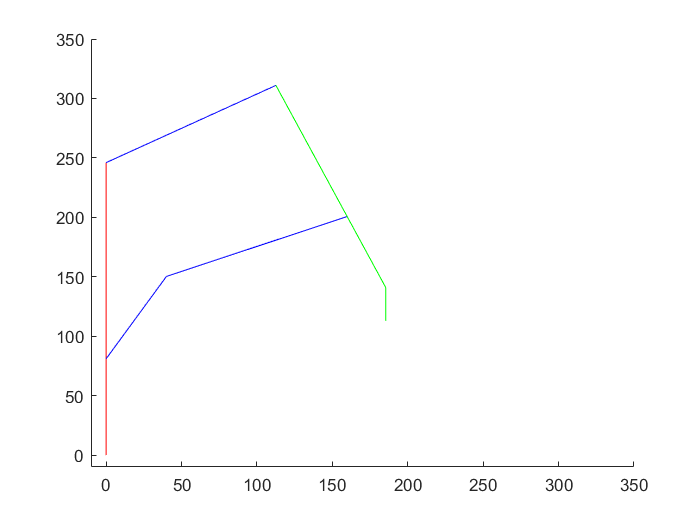

ans =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 28
          X: [0 81]
          Z: [0 246]
    phiXmin: 0.2000
    phiXmax: 1.4708
    phiZmin: -0.4000
    phiZmax: 0.3000
    phi1min: -2.3562
    phi1max: 2.3562
      theta: 0
          A: [112.5833 311]
          B: [159.8284 200.6918]
          C: [185.4196 140.9415]
          D: [185.4196 112.9415]
          E: [40.0000 150.2820]
       phiX: 1.0472
       phiZ: 0.5236
       phi1: -0.6490


x.draw()

### Testing the function on many possible angles

tic
for phiX=x.phiXmin:x.phiXmax
    phiX;
    for phiZ=x.phiZmin:x.phiZmax
        phiZ;
        x.phiZ = phiX/360 * 2 * pi;
        x.phiX = phiZ/360 * 2 * pi;
        x.phiZXtoFullpos(false); 
        x.validate(false); %validating the position
    end
end
toc

Elapsed time is 0.012960 seconds.


pos = ArmPos();
pos.phiX = 1.1476;
pos.phiZ = -0.2117;
pos = pos.phiZXtoFullpos(true);

correct pos found


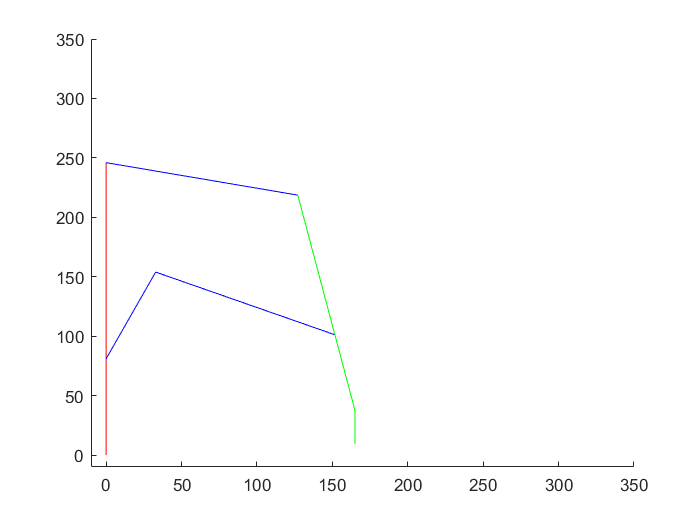

ans =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 28
          X: [0 81]
          Z: [0 246]
    phiXmin: 0.2000
    phiXmax: 1.4708
    phiZmin: -0.4000
    phiZmax: 0.3000
    phi1min: -2.3562
    phi1max: 2.3562
      theta: 0
          A: [127.0978 218.6841]
          B: [151.6879 101.2306]
          C: [165.0075 37.6100]
          D: [165.0075 9.6100]
          E: [32.8542 153.9425]
       phiX: 1.1476
       phiZ: -0.2117
       phi1: -1.5651


pos = pos.setD();
pos.draw()

D = [193,9.6];
pos2 = KineMod.IK_MAU(pos2.D,true);

PhiZ is invalid
PhiZ is invalid
CtoA: No valid positions found
failed to find the A coordinate


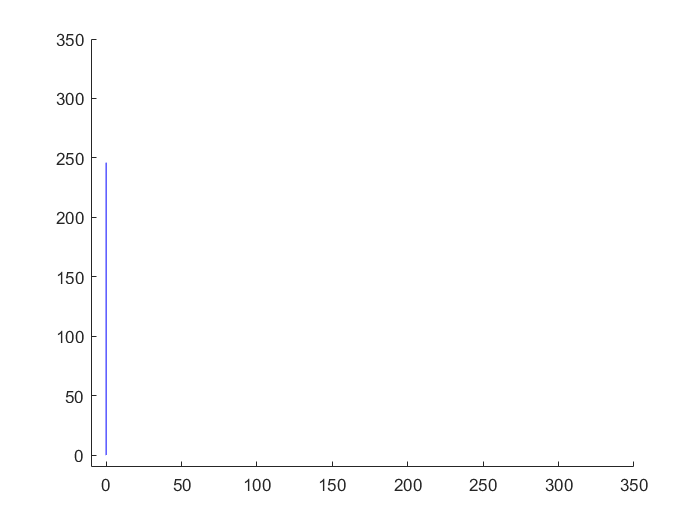

ans =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 28
          X: [0 81]
          Z: [0 246]
    phiXmin: 0.2000
    phiXmax: 1.4708
    phiZmin: -0.4000
    phiZmax: 0.3000
    phi1min: -2.3562
    phi1max: 2.3562
      theta: 0
          A: [0 0]
          B: [0 0]
          C: [0 0]
          D: [0 0]
          E: [0 0]
       phiX: 0
       phiZ: 0
       phi1: 0


pos2.draw()